[ispc isunix]

% set cwd
if ispc
    % Code to run on Windows platform
    homedir = fullfile('G:','My Drive','MATLAB');
    audiodir = fullfile(homedir,'Audio');
    HMD_dir = fullfile(audiodir,'HMD_ID')
    cd(HMD_dir);
    currentFolder = pwd
    datapath="D:\MatlabData\HMD\audio_flat_10s"
elseif isunix
    % Code to run on Linux platform
    homedir = '/home/ganesh/GoogleDrive/MATLAB';
    audiodir = append(homedir,"/Audio");
    cd(audiodir);
    currentFolder = pwd
    datapath="/home/ganesh/matlab_r2021b/data_is_here/RagaID";
else
    disp('Platform not supported')
end

HMD_dir = 'G:\My Drive\MATLAB\Audio\HMD_ID'

currentFolder = 'G:\My Drive\MATLAB\Audio\HMD_ID'

datapath = "D:\MatlabData\HMD\audio_flat_10s"

rng(123)

## Load and split data

The images are stored in the folder `Spectrograms`. The data for each class is seperated in subfolders, labelled by the folder name.

Split the data so that 80% of the images are used for training, 10% are used for validation, and the rest are used for testing.

img_size = [300 300]

img_size =    400   400


imds = imageDatastore(datapath,'IncludeSubfolders',true,'LabelSource','foldernames','FileExtensions','.jpg','ReadFcn',@(f) imresize(imread(f),[img_size(1) img_size(2)]))

imds =   ImageDatastore with properties:

                       Files: {
                              'D:\MatlabData\HMD\audio_flat_10s\Abhogi\Abhogi10_000SR_00_10swav.jpg';
                              'D:\MatlabData\HMD\audio_flat_10s\Abhogi\Abhogi10_000SR_01_10swav.jpg';
                              'D:\MatlabData\HMD\audio_flat_10s\Abhogi\Abhogi10_000SR_02_10swav.jpg'
                               ... and 1881 more
                              }
                     Folders: {
                              'D:\MatlabData\HMD\audio_flat_10s'
                              }
                      Labels: [Abhogi; Abhogi; Abhogi ... and 1881 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @(f)imresize(imread(f),[img_

[trainImgs,valImgs,testImgs] = splitEachLabel(imds,0.8,0.1,0.1,'randomized');
imgReSz_train1 = read(trainImgs);
whos imgReSz_train1 

  Name                  Size                Bytes  Class    Attributes

  imgReSz_train1      400x400x3            480000  uint8              



imgReSz1_val1 = read(valImgs);
whos imgReSz1_val1 

  Name                 Size                Bytes  Class    Attributes

  imgReSz1_val1      400x400x3            480000  uint8              



imgReSz1_test1 = read(testImgs);
whos imgReSz1_test1 

  Name                  Size                Bytes  Class    Attributes

  imgReSz1_test1      400x400x3            480000  uint8              



disp(countEachLabel(trainImgs))

    Label     Count
    ______    _____

    Abhogi     823 
    Basant     684 



disp(countEachLabel(valImgs))

    Label     Count
    ______    _____

    Abhogi     103 
    Basant      86 



categories(trainImgs.Labels)

ans = 2×1 cell array
    {'Abhogi'}
    {'Basant'}


% if ~isempty(ver('parallel'))
%     pool = gcp;
%     numPar = numpartitions(ADS,pool)
% else
%     numPar = 1
% end

Starting parallel pool (parpool) using the 'local' profile ...



numClasses = numel(categories(trainImgs.Labels));
dropoutProb = 0.2;
layers = [
    imageInputLayer([img_size(1) img_size(2) 3])
    %1st pooling layer
    convolution2dLayer(3,32,'Stride',1,'Padding','same')
    %batchNormalizationLayer
    reluLayer
    %dropoutLayer(dropoutProb)
    maxPooling2dLayer(3,'Stride',3)

    %2nd pooling layer
    convolution2dLayer(3,64,'Stride',1,'Padding','same')
    %batchNormalizationLayer
    reluLayer
    %dropoutLayer(dropoutProb)
    maxPooling2dLayer(2,'Stride',2)

    %3rd pooling layer
    convolution2dLayer(3,64,'Stride',1,'Padding','same')
    %batchNormalizationLayer
    reluLayer
    %dropoutLayer(dropoutProb)
    maxPooling2dLayer(2,'Stride',2)

    %4th pooling layer
    convolution2dLayer(3,64,'Stride',1,'Padding','same')
    batchNormalizationLayer
    reluLayer
    dropoutLayer(dropoutProb)
    maxPooling2dLayer(2,'Stride',2)

    %FC layer 1
    fullyConnectedLayer(512)
    dropoutLayer(dropoutProb)

    %FC layer 2
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer
]

layers =   20×1 Layer array with layers:

     1   ''   Image Input             400×400×3 images with 'zerocenter' normalization
     2   ''   Convolution             32 3×3 convolutions with stride [1  1] and padding 'same'
     3   ''   ReLU                    ReLU
     4   ''   Max Pooling             3×3 max pooling with stride [3  3] and padding [0  0  0  0]
     5   ''   Convolution             64 3×3 convolutions with stride [1  1] and padding 'same'
     6   ''   ReLU                    ReLU
     7   ''   Max Pooling             2×2 max pooling with stride [2  2] and padding [0  0  0  0]
     8   ''   Convolution             64 3×3 convolutions with stride [1  1] and padding 'same'
     9   ''   ReLU                    ReLU
    10   ''   Max Pooling             2×2 max pooling with stride [2  2] and padding [0  0  0  0]
    11   ''   Convolution             64 3×3 convolutions with stride [1  1] and pa

% numClasses = numel(categories(trainImgs.Labels));
% dropoutProb = 0.2;
% layers = [
%     imageInputLayer([400 400 3])
% 
%     convolution2dLayer(3,16,'Padding','same')
%     batchNormalizationLayer
%     reluLayer
% 
%     maxPooling2dLayer(2,'Stride',2)
% 
%     convolution2dLayer(3,32,'Padding','same')
%     batchNormalizationLayer
%     reluLayer
% 
%     maxPooling2dLayer(2,'Stride',2,'Padding',[0,1])
% 
%     dropoutLayer(dropoutProb)
%     convolution2dLayer(3,64,'Padding','same')
%     batchNormalizationLayer
%     reluLayer
% 
%     dropoutLayer(dropoutProb)
%     convolution2dLayer(3,64,'Padding','same')
%     batchNormalizationLayer
%     reluLayer
% 
%     maxPooling2dLayer(2,'Stride',2,'Padding',[0,1])
% 
%     dropoutLayer(dropoutProb)
%     convolution2dLayer(3,64,'Padding','same')
%     batchNormalizationLayer
%     reluLayer
% 
%     dropoutLayer(dropoutProb)
%     convolution2dLayer(3,64,'Padding','same')
%     batchNormalizationLayer
%     reluLayer
% 
%     maxPooling2dLayer([1 13])
% 
%     fullyConnectedLayer(numClasses)
%     softmaxLayer
%     classificationLayer]

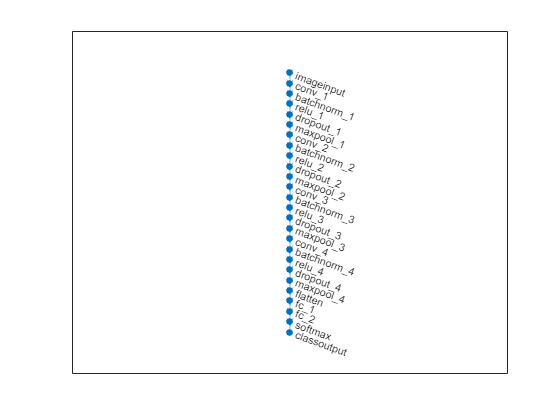

lgraph = layerGraph(layers);
figure
plot(lgraph)

miniBatchSize = 16;
initialLearnRate = 0.000001;
maxEpochs = 100;

options = trainingOptions('adam', ...
    'InitialLearnRate',initialLearnRate, ...
    'MaxEpochs',maxEpochs, ...
    'LearnRateSchedule',"piecewise",...
    'LearnRateDropFactor',.1,...
    'LearnRateDropPeriod',50,...
    'MiniBatchSize',miniBatchSize, ...
    'Shuffle','every-epoch', ...
    'Plots','training-progress', ...
    'ValidationData',valImgs,...
    'DispatchInBackground',1, ... 
    'ValidationFrequency',ceil(numel(trainImgs.Files)/miniBatchSize),...
    'ValidationPatience',20, ...
    'OutputNetwork','best-validation-loss', ...
    'ExecutionEnvironment','gpu')

% options = trainingOptions('adam', ...
%     'InitialLearnRate',initialLearnRate, ...

options =   TrainingOptionsADAM with properties:

             GradientDecayFactor: 0.9000
      SquaredGradientDecayFactor: 0.9990
                         Epsilon: 1.0000e-08
                InitialLearnRate: 1.0000e-06
               LearnRateSchedule: 'piecewise'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 50
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                       MaxEpochs: 100
                   MiniBatchSize: 16
                         Verbose: 1
                VerboseFrequency: 50
                  ValidationData: [1×1 matlab.io.datastore.ImageDatastore]
             ValidationFrequency: 95
              ValidationPatience: 20
                         Shuffle: 'every-epoch'
                  CheckpointPath: ''
            ExecutionEnvironment: 'gpu'
                     

%     'MaxEpochs',maxEpochs, ...
%     'LearnRateSchedule',"piecewise",...
%     'LearnRateDropFactor',.1,...
%     'LearnRateDropPeriod',30,...
%     'MiniBatchSize',miniBatchSize, ...
%     'Shuffle','every-epoch', ...
%     'Plots','none', ...
%     'ValidationData',valImgs,...
%     'DispatchInBackground',1, ... 
%     'ValidationFrequency',ceil(numel(trainImgs.Files)/miniBatchSize),...
%     'ValidationPatience',10, ...
%     'OutputNetwork','best-validation-loss', ...
%     'ExecutionEnvironment','gpu')

Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:08 |       68.75% |       51.85% |       0.6283 |       0.9286 |      1.0000e-06 |


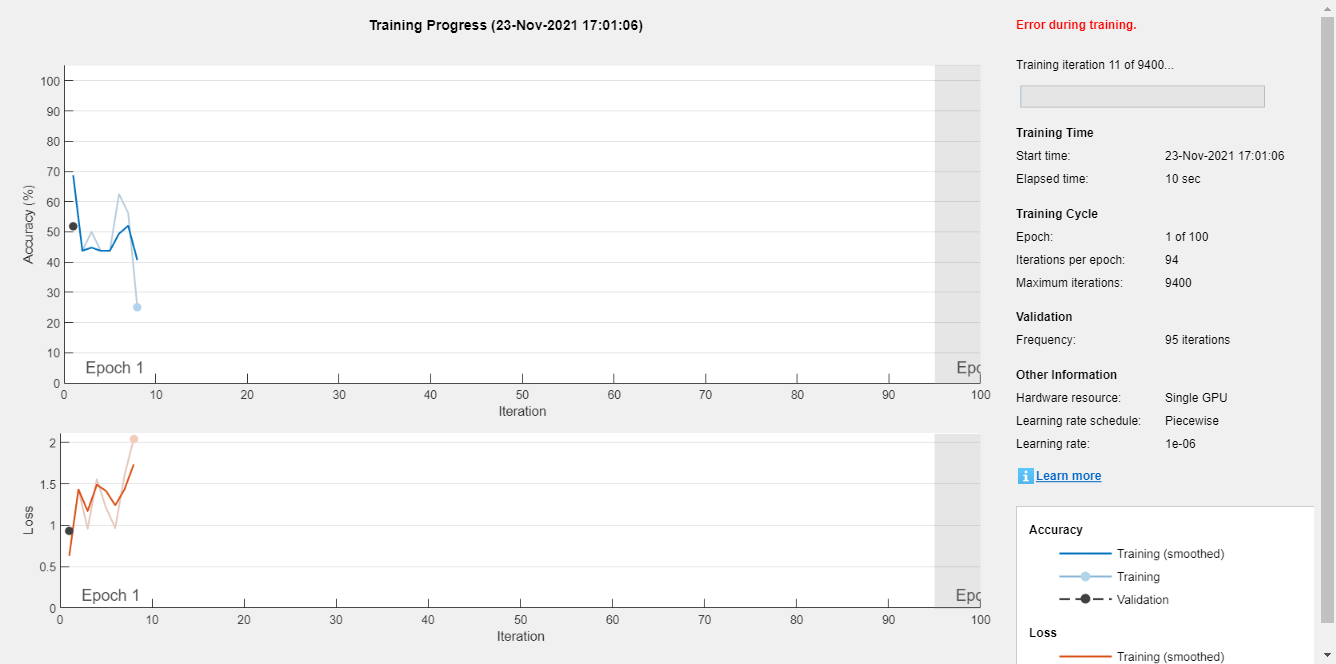

Error using trainNetwork (line 184)
Out of memory.

Caused by:
    Error using nnet.internal.cnn.dispatcher.MiniBatchNDDatastoreDispatcher>iCellToArray (line 461)
    Out of memory.

<a href="matlab:helpview('matlab','error_nomem')" style="font-weigh

 trainednet = trainNetwork(trainImgs,layers,options)

save('trainednet.mat',"trainednet")

gpuDevice(1)

ans =   CUDADevice with properties:

                      Name: 'GeForce RTX 2060'
                     Index: 1
         ComputeCapability: '7.5'
            SupportsDouble: 1
             DriverVersion: 11.2000
            ToolkitVersion: 11
        MaxThreadsPerBlock: 1024
          MaxShmemPerBlock: 49152
        MaxThreadBlockSize: [1024 1024 64]
               MaxGridSize: [2.1475e+09 65535 65535]
                 SIMDWidth: 32
               TotalMemory: 6.4425e+09
           AvailableMemory: 5.2270e+09
       MultiprocessorCount: 30
              ClockRateKHz: 1200000
               ComputeMode: 'Default'
      GPUOverlapsTransfers: 1
    KernelExecutionTimeout: 1
          CanMapHostMemory: 1
           DeviceSupported: 1
           DeviceAvailable: 1
            DeviceSelected: 1


predict = classify(trainednet,testImgs, 'ExecutionEnvironment','cpu')

predict = 188×1 categorical array
     Abhogi 
     Abhogi 
     Abhogi 
     Abhogi 
     Abhogi 
     Abhogi 
     Abhogi 
     Basant 
     Abhogi 
     Abhogi 
     Abhogi 
     Basant 
     Abhogi 
     Abhogi 
     Abhogi 
     Abhogi 
     Abhogi 
     Basant 
     Abhogi 
     Abhogi 
     Abhogi 
     Abhogi 
     Abhogi 
     Abhogi 
     Abhogi 
     Abhogi 
     Abhogi 
     Abhogi 
     Abhogi 
     Abhogi 


acc = mean(testImgs.Labels==predict)

acc = 0.9202

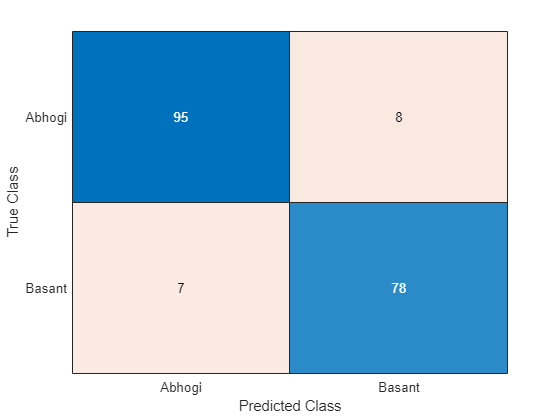

confusionchart(testImgs.Labels,predict)

layers =   30×1 Layer array with layers:

     1   ''   Image Input             400×400×3 images with 'zerocenter' normalization
     2   ''   Convolution             16 3×3 convolutions with stride [1  1] and padding 'same'
     3   ''   Batch Normalization     Batch normalization
     4   ''   ReLU                    ReLU
     5   ''   Max Pooling             2×2 max pooling with stride [2  2] and padding [0  0  0  0]
     6   ''   Convolution             32 3×3 convolutions with stride [1  1] and padding 'same'
     7   ''   Batch Normalization     Batch normalization
     8   ''   ReLU                    ReLU
     9   ''   Max Pooling             2×2 max pooling with stride [2  2] and padding [0  0  1  1]
    10   ''   Dropout                 20% dropout
    11   ''   Convolution             64 3×3 convolutions with stride [1  1] and padding 'same'
    12   ''   Batch Normalization     Batch normalization


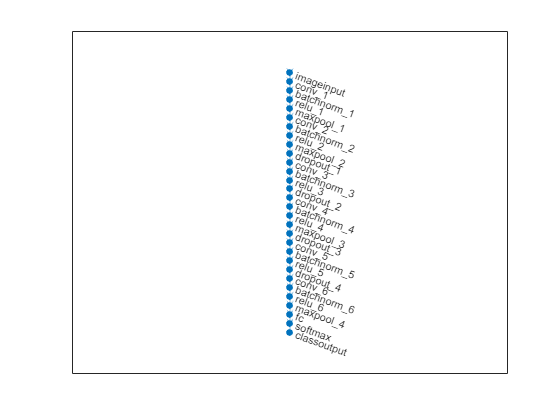

options =   TrainingOptionsADAM with properties:

             GradientDecayFactor: 0.9000
      SquaredGradientDecayFactor: 0.9990
                         Epsilon: 1.0000e-08
                InitialLearnRate: 1.0000e-06
               LearnRateSchedule: 'piecewise'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 30
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                       MaxEpochs: 30
                   MiniBatchSize: 8
                         Verbose: 1
                VerboseFrequency: 50
                  ValidationData: [1×1 matlab.io.datastore.ImageDatastore]
             ValidationFrequency: 189
              ValidationPatience: Inf
                         Shuffle: 'every-epoch'
                  CheckpointPath: ''
            ExecutionEnvironment: 'gpu'
                     

Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:05 |       50.00% |       46.03% |       1.8894 |       1.4408 |      1.0000e-06 |
|       1 |          50 |       00:00:13 |       37.50% |              |       1.2531 |              |      1.0000e-06 |
|       1 |         100 |       00:00:21 |       50.00% |              |       0.6924 |              |      1.0000e-06 |
|       1 |         150 |       00:00:29 |       62.50% |              |       0.7317 |              |      1.0000

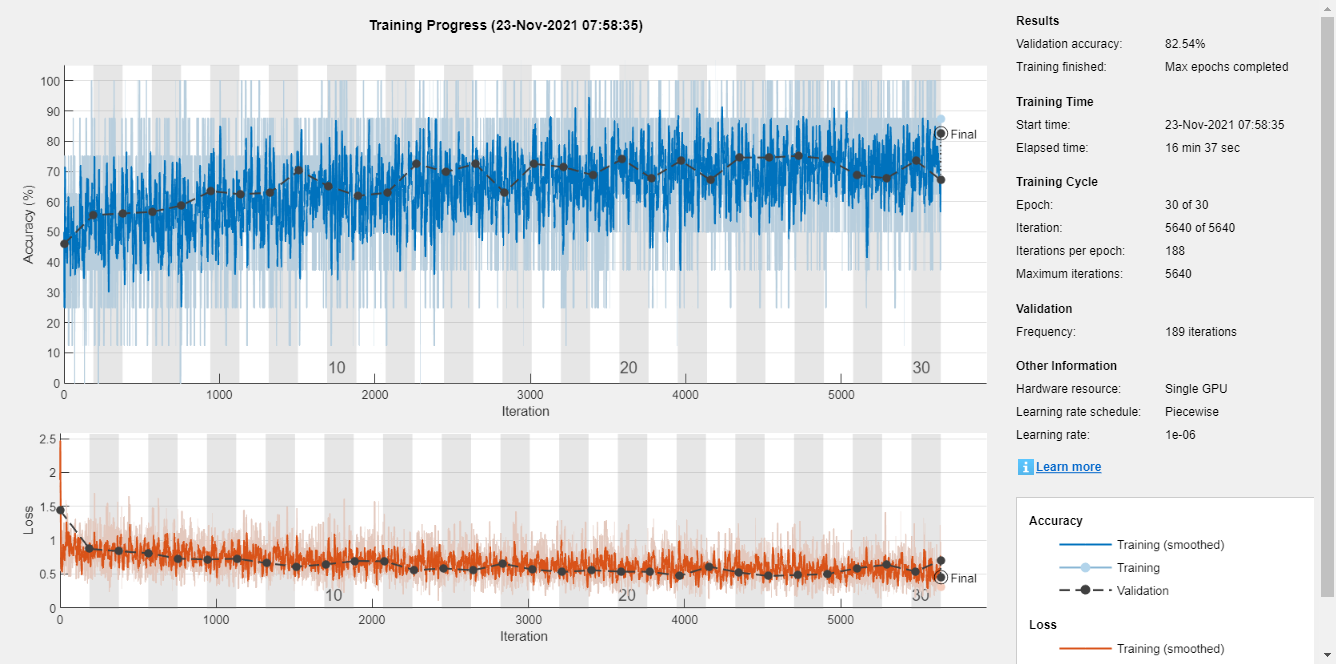

trainednet =   SeriesNetwork with properties:

         Layers: [30×1 nnet.cnn.layer.Layer]
     InputNames: {'imageinput'}
    OutputNames: {'classoutput'}
